Question 1

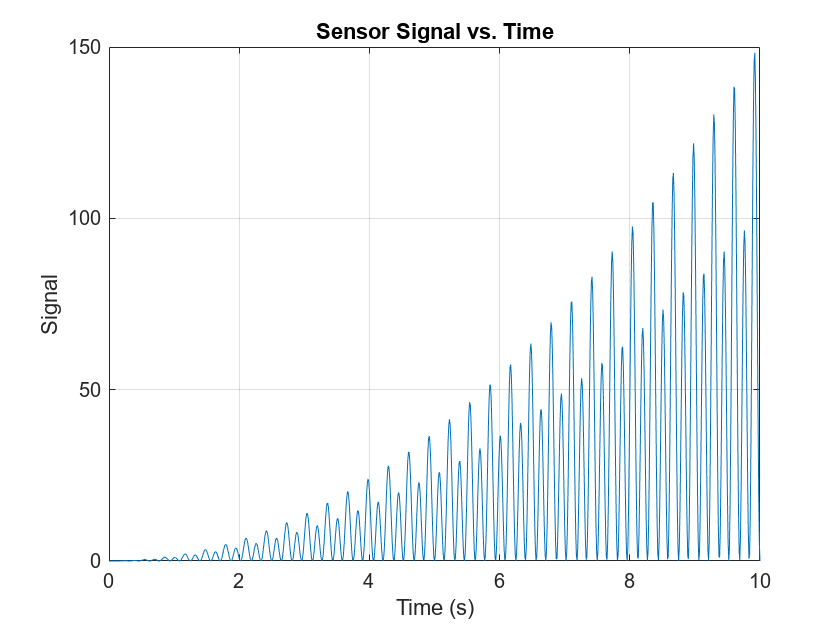

%a
f = 1.6;
t = 0:0.01:10;

signal = 5*t.^2 .* cos(2*pi*f*t + 0.1).^2 .* sin(2*pi*f*t).^2;

figure;
plot(t, signal);
xlabel('Time (s)');
ylabel('Signal');
title('Sensor Signal vs. Time');
grid on;


%b
a = 6.5; 
b = 6.9; 
epsilon = 1e-5;

phi = (1 + sqrt(5)) / 2;

func = @(t) 5*t.^2 .* cos(2*pi*f*t + 0.1).^2 .* sin(2*pi*f*t).^2;

while (b - a) > epsilon
    c = b - (b - a) / phi;
    d = a + (b - a) / phi;
    
    if func(c) < func(d)
        b = d;
    else
        a = c;
    end
end


t_opt = (a + b) / 2;
min_val = func(t_opt);

fprintf('The minimum of the function within the given range occurs at t = %.5f seconds, with a value of %.5f.\n', t_opt, min_val);

The minimum of the function within the given range occurs at t = 6.70880 seconds, with a value of 0.00000.


Question 2

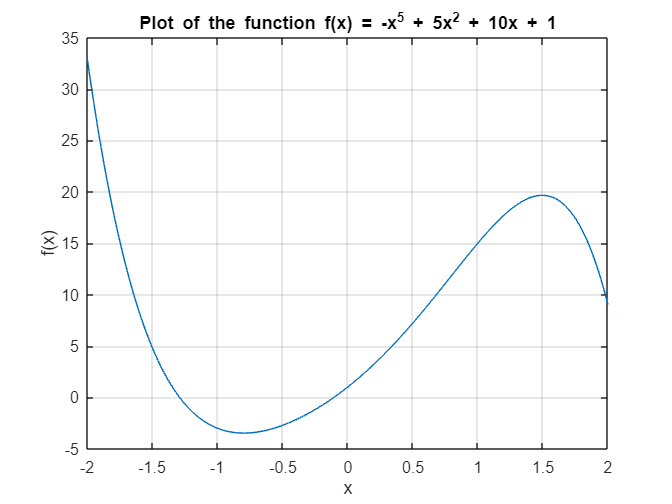

%a
f = @(x) -x.^5 + 5*x.^2 + 10*x + 1;

x = linspace(-2, 2, 400);
y = f(x);

figure;
plot(x, y)
xlabel('x')
ylabel('f(x)')
title('Plot of the function f(x) = -x^5 + 5x^2 + 10x + 1')
grid on


%b
df = @(x) -5*x.^4 + 10*x + 10;

x_eval = -1.5;
derivative_value = df(x_eval);
disp(['The derivative at x = -1.5 is: ', num2str(derivative_value)])

The derivative at x = -1.5 is: -30.3125



%c
x_start = -1.5;
h = 0.1;

if f(x_start + h) < f(x_start)
    direction = 1; 
else
    direction = -1;
end

x1 = x_start + direction * h;
x2 = x_start + direction * 2 * h;
f1 = f(x1);
f2 = f(x2);

disp(['Point 1: x = ', num2str(x1), ', f(x) = ', num2str(f1)]);

Point 1: x = -1.4, f(x) = 2.1782


disp(['Point 2: x = ', num2str(x2), ', f(x) = ', num2str(f2)]);

Point 2: x = -1.3, f(x) = 0.16293



%d
x = -1.5; 
h = 0.1; 
f_current = f(x);

while true
    x_left = x - h;
    x_right = x + h;
    f_left = f(x_left);
    f_right = f(x_right);
    
    if f_left > f_current && f_current < f_right
        break; 
    else
        h = 2 * h; 
        if f_left < f_current
            x = x_left;
        else
            x = x_right; 
        end
        f_current = f(x);
    end
end

x1 = x - h; 
x2 = x; 
x3 = x + h;
disp(['Unimodal interval points and their function values:']);

Unimodal interval points and their function values:


disp(['x1 = ', num2str(x1), ', f(x1) = ', num2str(f(x1))]);

x1 = -1.6, f(x1) = 8.2858


disp(['x2 = ', num2str(x2), ', f(x2) = ', num2str(f(x2))]);

x2 = -0.8, f(x2) = -3.4723


disp(['x3 = ', num2str(x3), ', f(x3) = ', num2str(f(x3))]);

x3 = 1.1102e-16, f(x3) = 1



%BONUS
syms x_sym;

Lagrange_poly = ((x_sym - x2) * (x_sym - x3) / ((x1 - x2) * (x1 - x3))) * f(x1) + ...
                ((x_sym - x1) * (x_sym - x3) / ((x2 - x1) * (x2 - x3))) * f(x2) + ...
                ((x_sym - x1) * (x_sym - x2) / ((x3 - x1) * (x3 - x2))) * f(x3);

min_Lagrange = min(Lagrange_poly);
min_x_Lagrange = vpasolve(diff(Lagrange_poly) == 0, x_sym); 

disp(['x value at the minimum: ', char(min_x_Lagrange)]);

x value at the minimum: -0.62044164037854884380809852421695


Question 3

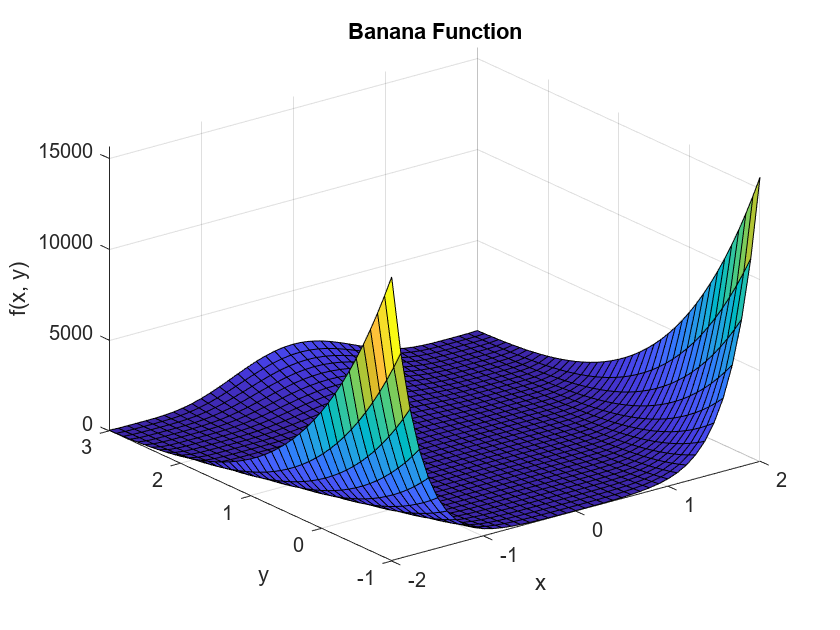

%a
bananaFunc = @(x) 25*(x(2) - x(1)^2)^4 + (1 - x(1))^2;
[X, Y] = meshgrid(-2:0.1:2, -1:0.1:3);
Z = 25*(Y - X.^2).^4 + (1 - X).^2;

surf(X, Y, Z)
xlabel('x')
ylabel('y')
zlabel('f(x, y)')
title('Banana Function')

 
 Iteration   Func-count     min f(x)         Procedure
     0            1                1         
     1            3           0.9995         initial simplex
     2            4           0.9995         reflect
     3            6         0.998501         expand
     4            8         0.998001         expand
     5           10         0.995755         expand
     6           12         0.993635         expand
     7           14         0.988098         expand
     8           16         0.981121         expand
     9           18         0.966673         expand
    10           20         0.945764         expand
    11           22          0.90729         expand
    12           24         0.848504         expand
    13           26         0.749123         expand
    14           28         0.601775         expand
    15           30         0.428136         expand
    16           31         0.428136         reflect
    17           33         0.428136         contract 

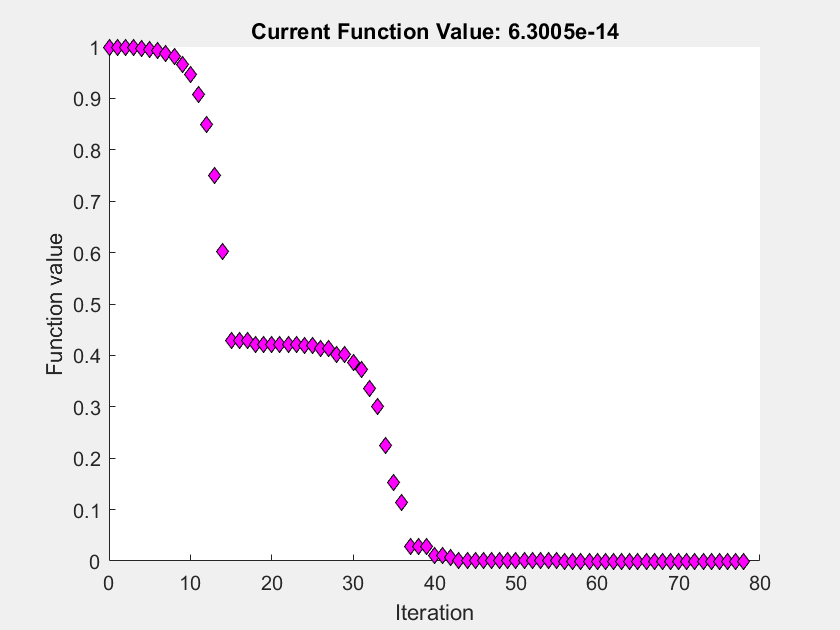

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 




options = optimset('Display', 'iter', 'PlotFcns', @optimplotfval);
[xMin, fValMin, exitflag, output] = fminsearch(bananaFunc, [0, 0], options);


%b
disp(['Minimum location: (', num2str(xMin(1)), ', ', num2str(xMin(2)), ')']);

Minimum location: (1, 1)


disp(['Function value at minimum: ', num2str(fValMin)]);

Function value at minimum: 6.3005e-14



%c
disp(['Total number of function evaluations: ', num2str(output.funcCount)]);

Total number of function evaluations: 148


disp(['Total number of iterations: ', num2str(output.iterations)]);

Total number of iterations: 78



%d
disp('Total number of each simplex maneuver (reflect, contract inside, contract outside, expand or shrink): 17,26,9,24,0');

Total number of each simplex maneuver (reflect, contract inside, contract outside, expand or shrink): 17,26,9,24,0
